# 2次元の固有値・固有ベクトルの図示

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all;
sympref('MatrixWithSquareBrackets',true);
A=[1 -1;-0.5 1.5];
sym(A)

$$ans = \left[\begin{array}{cc} 1 & -1\\ -0.5000 & 1.5000 \end{array}\right]$$

固有値・固有ベクトルを求める

[V,D]=eig(A)

V =    -0.8944    0.7071
   -0.4472   -0.7071


D =     0.5000         0
         0    2.0000


V(:,1)=V(:,1)/V(1,1);
V(:,2)=V(:,2)/V(1,2);
V

V =     1.0000    1.0000
    0.5000   -1.0000


c=[2;1];
x=V*c

x =      3
     0


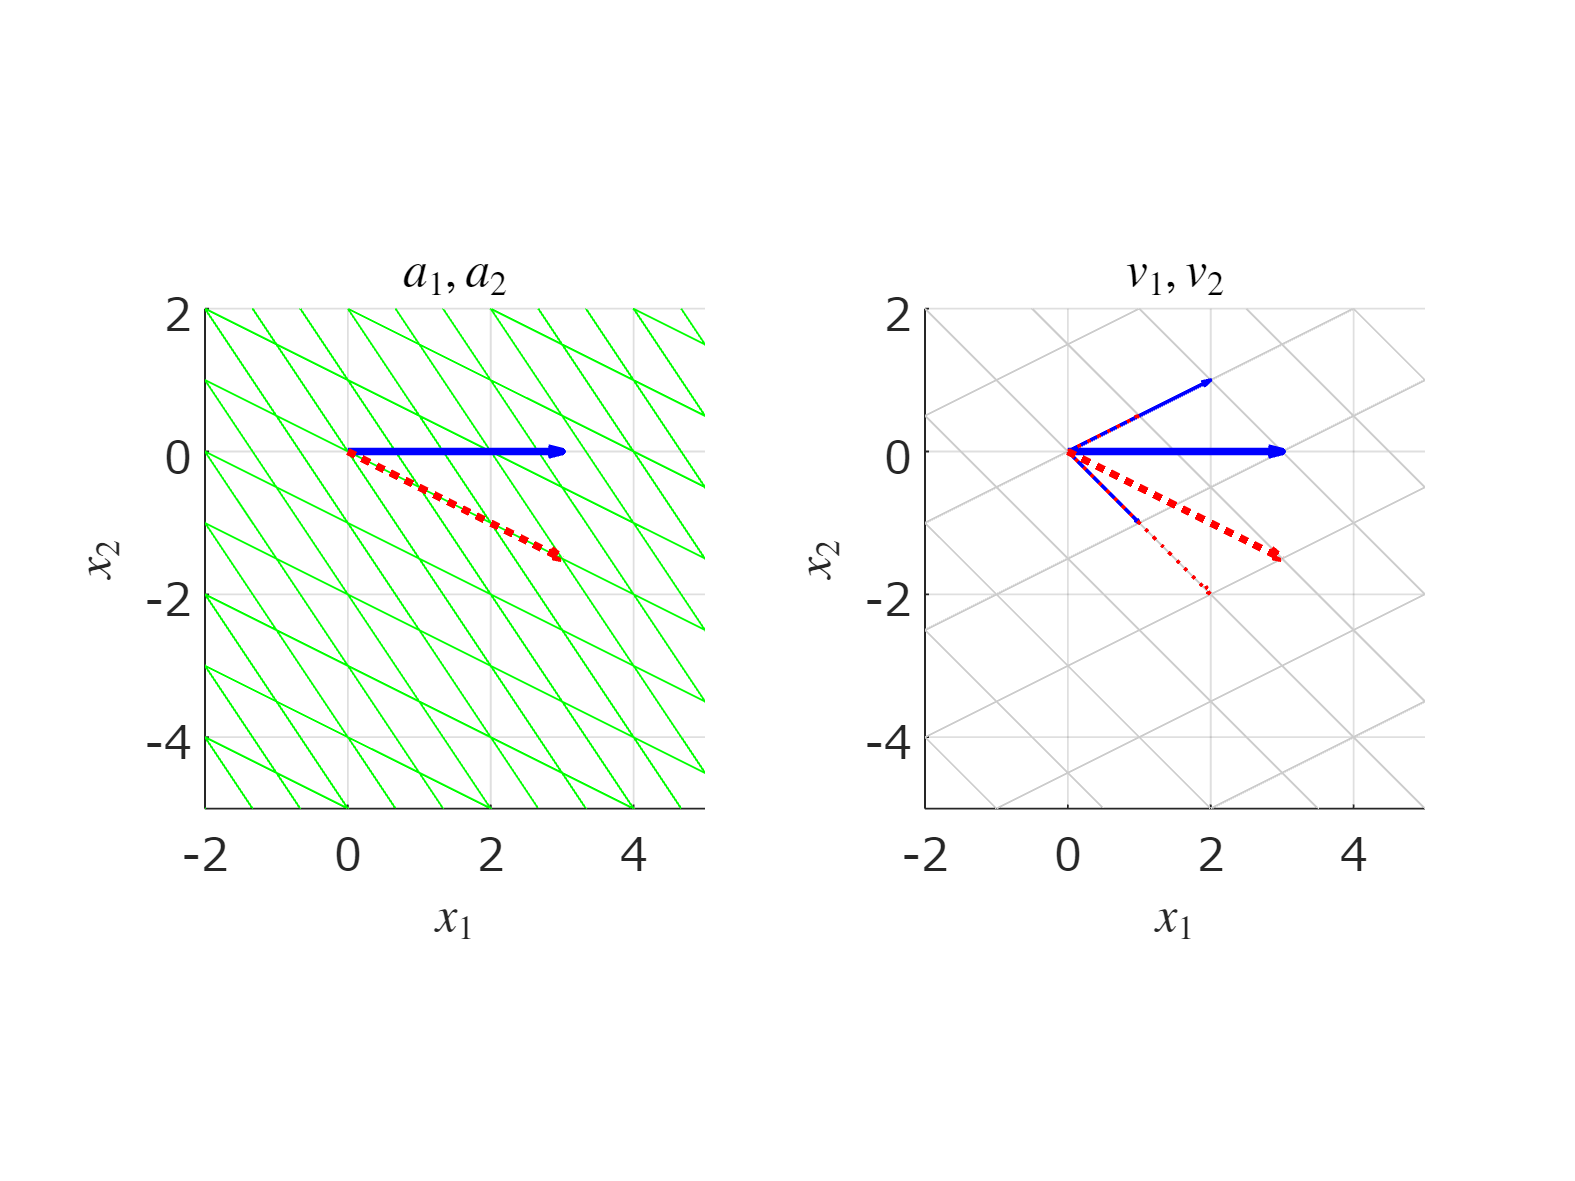

y=A*x;

figure;
tiledlayout(1,2);nexttile;
hold on;
grid on;axis equal;
set(gca,'fontname','メイリオ','fontsize',12);
gridTciks=9;
X=zeros(gridTciks*2+1,gridTciks*2+1);
Y=zeros(gridTciks*2+1,gridTciks*2+1);
Z=zeros(gridTciks*2+1,gridTciks*2+1);
for n1=-gridTciks:gridTciks
    for n2=-gridTciks:gridTciks
        tmpV=n1*A(:,1)+n2*A(:,2);
        X(n1+gridTciks+1,n2+gridTciks+1)=tmpV(1);
        Y(n1+gridTciks+1,n2+gridTciks+1)=tmpV(2);
        Z(n1+gridTciks+1,n2+gridTciks+1)=0;

    end
end
mesh(X,Y,Z,'FaceAlpha',0,'EdgeColor','g');
quiver(0, 0, x(1), x(2),'b-','LineWidth',2,'AutoScale','off');
quiver(0, 0, y(1), y(2),'r:','LineWidth',2,'AutoScale','off');
axis(5*[-0.4 1 -1 0.4]);
xlabel('$x_1$','Interpreter','latex');ylabel('$x_2$','Interpreter','latex');
title(['$a_1, a_2$'],'Interpreter','latex')
nexttile;
grid on;hold on;axis equal;
set(gca,'fontname','メイリオ','fontsize',12);

gridTciks=7;
X2=zeros(gridTciks*2+1,gridTciks*2+1);
Y2=zeros(gridTciks*2+1,gridTciks*2+1);
Z2=zeros(gridTciks*2+1,gridTciks*2+1);
for n1=-gridTciks:gridTciks
    for n2=-gridTciks:gridTciks
        tmpV=n1*V(:,1)+n2*V(:,2);
        X2(n1+gridTciks+1,n2+gridTciks+1)=tmpV(1);
        Y2(n1+gridTciks+1,n2+gridTciks+1)=tmpV(2);
        Z2(n1+gridTciks+1,n2+gridTciks+1)=0;
        
    end
end
mesh(X2,Y2,Z2,'FaceAlpha',0,'EdgeColor',0.8*[1 1 1]);view(0,90);
quiver(0, 0, x(1), x(2),'b-','LineWidth',2,'AutoScale','off');
quiver(0, 0, c(1)*V(1,1), c(1)*V(2,1), 'b-','LineWidth',1,'AutoScale','off');
quiver(0, 0, c(2)*V(1,2), c(2)*V(2,2), 'b-','LineWidth',1,'AutoScale','off');
quiver(0, 0, y(1), y(2),'r:','LineWidth',2,'AutoScale','off');
quiver(0, 0, D(1,1)*c(1)*V(1,1), D(1,1)*c(1)*V(2,1), 'r:','LineWidth',1,'AutoScale','off');
quiver(0, 0, D(2,2)*c(2)*V(1,2), D(2,2)*c(2)*V(2,2), 'r:','LineWidth',1,'AutoScale','off');
axis(5*[-0.4 1 -1 0.4]);
xlabel('$x_1$','Interpreter','latex');ylabel('$x_2$','Interpreter','latex');

title(['$v_1, v_2$'],'Interpreter','latex')
exportgraphics(gcf,'fig_eigValVecSample02.pdf')